clear
clc
close all
%format shortG
%format compact

## PARAMETERS

clear
clc
close all

cancerData = readtable("cancer_reg.csv");

% output
targets = cancerData.PctPrivateCoverageAlone';

% inputs
inputs = cancerData;
inputs = removevars(inputs,{'TARGET_deathRate', 'MedianAgeMale', 'MedianAgeFemale', ...
                            'binnedInc', 'avgAnnCount',  'avgDeathsPerYear', ...
                            'Geography', 'PctSomeCol18_24', 'PctBachDeg25_Over', ...
                            'PctEmployed16_Over', 'PctPrivateCoverageAlone'});
inputs = table2array(inputs)';

## ALGORITHM PARAMETERS

%[numHL, l1size, l2size, trainFCn, epochs, lr, m, tf1, tf2]

lb = [1 4   4 1  50   1e-2 0.5 1 1]; % lower bound
ub = [2 20 20 14 2000 1    0.98 15 15];  % upper bound
  
options = optimoptions(@particleswarm, 'MaxTime', 1*60*60,'Display','iter', 'PlotFcn', 'pswplotbestf','MaxIterations',200);%, ...
                    %'PlotFcn', 'gaplotbestf');


## ALGORITHM: PARTICLE SWARM


                                 Best            Mean     Stall
Iteration     f-count            f(x)            f(x)    Iterations
    0              90       0.0009466       1.014e+06        0
    1             180       0.0009355           212.1        0
    2             270       0.0008537         0.09377        0
    3             360        0.000652          0.0288        0
    4             450        0.000652            5804        1
    5             540        0.000652         0.02453        2
    6             630        0.000652          0.0762        3
Optimization ended: the total optimization time in seconds exceeded OPTIONS.MaxTime.


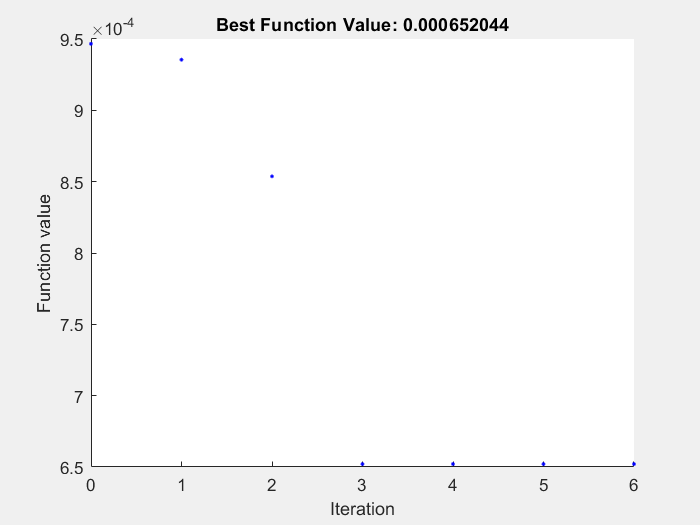

tic

ObjFcn = makeObjFcn(inputs, targets);

[X, fbest, exitflag,out] = particleswarm(ObjFcn,9,lb,ub,options);

toc

Elapsed time is 4391.333116 seconds.


disp(X)

   1.0e+03 *

    0.0010    0.0200    0.0148    0.0017    1.0215    0.0000    0.0006    0.0081    0.0045



trainList = {'trainlm' ,'trainbr', 'trainbfg' ,'traincgb', 'traincgf', 'traingd', 'traingda', 'traingdm', 'traingdx', 'trainoss', 'trainrp', 'trainscg', 'trainb', 'trains'}; %ub 15
actFunc = {'logsig', 'tansig', 'satlins','purelin', 'poslin', 'satlin', 'compet', 'elliotsig', 'hardlim', 'hardlims', 'netinv', 'radbas', 'radbasn', 'softmax', 'tribas'}; %ub 15
%vals = [round(X(1)), round(X(2)),round(X(3)), char(trainList(round(X(4)))), round(X(5)), X(6), X(7) , char(actFunc(round(X(8)))),char(actFunc(round(X(9))))]
vals = [round(X(1)) round(X(2)) round(X(3))  (trainList(round(X(4)))) round(X(5)) X(6) X(7)  (actFunc(round(X(8)))) (actFunc(round(X(9))))]

vals = 1×9 cell array
    {[1]}    {[20]}    {[15]}    {'trainbr'}    {[1022]}    {[0.0100]}    {[0.6355]}    {'elliotsig'}    {'purelin'}


names = ["HL", "L1size", "L2size", "trainFcn", "maxEpoch", "lr", "m", "actF1", "actF2"]

names = 1×9 string array
    "HL"    "L1size"    "L2size"    "trainFcn"    "maxEpoch"    "lr"    "m"    "actF1"    "actF2"



%["HL: ", round(X(1)), ' L1size: ', , ' L2size: ', , ' trainFcn: ', , ' maxEpoch: ', , ' lr: ', ' m: ', ];
%T = table();

## FUNCTION: OUTPUT TO OPTIMIZE

function ObjFcn = makeObjFcn(XTrain,YTrain)
    ObjFcn = @valErrorFun;
        function valError = valErrorFun(OptVars)
            
          % Solve an Input-Output Fitting problem with a Neural Network
          % Choose a Training Function
          trainList = {'trainlm' ,'trainbr', 'trainbfg' ,'traincgb', 'traincgf', 'traingd', 'traingda', 'traingdm', 'traingdx', 'trainoss', 'trainrp', 'trainscg', 'trainb', 'trains'}; %ub 15
          trainF = round(OptVars(4));
          
          trainFcn = char(trainList{trainF});  % Bayesian Regularization backpropagation.
          % Create a Fitting Network
          layer1_size = round(OptVars(2));
          layer2_size = round(OptVars(3));
          maxEpochs = round(OptVars(5));
          LR = OptVars(6);
          Momentum = OptVars(7);
          
          actFunc = {'logsig', 'tansig', 'satlins','purelin', 'poslin', 'satlin', 'compet', 'elliotsig', 'hardlim', 'hardlims', 'netinv', 'radbas', 'radbasn', 'softmax', 'tribas'}; %ub 15
          actF1 = round(OptVars(8));
          actF2 = round(OptVars(9));
          TrainFcn1 = actFunc(actF1);
          TrainFcn2 = actFunc(actF2);
          if round(OptVars(1)) == 2 
            hiddenLayerSizes = [layer1_size layer2_size];
          else 
              hiddenLayerSizes = [layer1_size];
          end
          net = fitnet(hiddenLayerSizes,trainFcn);
    
          % Setup Division of Data for Training, Validation, Testing
          net.divideParam.trainRatio = 70/100;
          net.divideParam.valRatio = 15/100;
          net.divideParam.testRatio = 15/100;
          
          % Activation function for hidden layers
          if round(OptVars(1)) == 2  
              net.layers{1}.transferFcn = char(TrainFcn1);  % Hidden layer 1
              net.layers{2}.transferFcn = char(TrainFcn2);  % Hidden layer 2
              net.layers{3}.transferFcn = 'purelin';  % Output layer
          else 
              net.layers{1}.transferFcn = char(TrainFcn1);  % Hidden layer 
              net.layers{2}.transferFcn = 'purelin';
          end
          % performance function
          net.performFcn = 'mse';
          net.performParam.normalization = 'standard';
          % Train the Network
          net.trainParam.showWindow = true;
          net.trainParam.showCommandLine = false;
          net.trainParam.lr = LR;
          net.trainParam.mc = Momentum;
          net.trainParam.epochs = maxEpochs;
          [net,~] = train(net,XTrain,YTrain);
          % Test the Network
          YPredicted = net(XTrain);
          valError = perform(net,YTrain,YPredicted);
          %['numHL: ', round(OptVars(1)), ' L1size: ',layer1_size, ' L2Size: ', layer2_size, ' trainFcn: ',trainFcn, ' maxepochs: ',maxEpochs, " lr: "]
        end
  end
